% =========================================================================
% Spread Spectrum Communication System: Performance Analysis
% Simulating BPSK DSSS with PN and Gold Codes over an AWGN Channel
% =========================================================================

clc; clear; close all;

%% 1. System Parameters
numBits = 1e5;                  % Number of data bits to simulate
EbNo_dB = 0:2:12;               % Range of Eb/No values in dB
poly1 = [5 2 0];                % Generator polynomial 1 (for PN & Gold)
poly2 = [5 4 3 2 0];            % Generator polynomial 2 (for Gold)
shift = 2;                      % Code phase shift
spreadingFactor = 31;           % Length of the spreading sequence (2^5 - 1)

%% 2. Spreading Code Generation
% Initialize PN Sequence Generator
pnGen = comm.PNSequence('Polynomial', poly1, ...
    'SamplesPerFrame', spreadingFactor, 'InitialConditions', [0 0 0 0 1]);

% Initialize Gold Sequence Generator
goldGen = comm.GoldSequence('FirstPolynomial', poly1, ...
    'SecondPolynomial', poly2, 'FirstInitialConditions', [0 0 0 0 1], ...
    'SecondInitialConditions', [0 0 0 0 1], 'Index', shift, ...
    'SamplesPerFrame', spreadingFactor);

% Generate one frame of spreading codes
pnCode = pnGen();
goldCode = goldGen();

% Convert codes from [0, 1] to bipolar [-1, 1] for spreading
pnCode_bipolar = 2*pnCode - 1;
goldCode_bipolar = 2*goldCode - 1;

%% 3. Pre-allocate Arrays for Performance Metrics
ber_unspread = zeros(1, length(EbNo_dB));
ber_pn = zeros(1, length(EbNo_dB));
ber_gold = zeros(1, length(EbNo_dB));

%% 4. Main Simulation Loop
disp('Initiating Monte Carlo Simulation for DSSS...');

Initiating Monte Carlo Simulation for DSSS...



for i = 1:length(EbNo_dB)
    
    % Generate random binary data
    data = randi([0 1], numBits, 1);
    
    % BPSK Modulation (0 -> -1, 1 -> 1)
    modData = 2*data - 1;
    
    % ---------------------------------------------------------------------
    % A. UNSPREAD SYSTEM (Baseline)
    % ---------------------------------------------------------------------
    % Add AWGN
    snr_unspread = EbNo_dB(i); 
    rx_unspread = awgn(modData, snr_unspread, 'measured');
    
    % Demodulation & BER Calculation
    rx_data_unspread = rx_unspread > 0;
    [~, ber_unspread(i)] = biterr(data, rx_data_unspread);
    
    % ---------------------------------------------------------------------
    % B. SPREAD SPECTRUM SYSTEM
    % ---------------------------------------------------------------------
    % Kronecker tensor product spreads each bit by the code sequence
    spreadData_pn = kron(modData, pnCode_bipolar);
    spreadData_gold = kron(modData, goldCode_bipolar);
    
    % Adjust SNR for the spreading factor (Processing Gain)
    % SNR = Eb/No - 10*log10(SpreadingFactor)
    snr_spread = EbNo_dB(i) - 10*log10(spreadingFactor);
    
    % Add AWGN to spread signals
    rx_spread_pn = awgn(spreadData_pn, snr_spread, 'measured');
    rx_spread_gold = awgn(spreadData_gold, snr_spread, 'measured');
    
    % Despreading process (correlate with the synchronized local code)
    % Reshape received signals into a matrix where each column is one spread bit
    rx_matrix_pn = reshape(rx_spread_pn, spreadingFactor, numBits);
    rx_matrix_gold = reshape(rx_spread_gold, spreadingFactor, numBits);
    
    % Multiply by local code and integrate (sum) over the chip period
    despread_pn = (pnCode_bipolar' * rx_matrix_pn)' / spreadingFactor;
    despread_gold = (goldCode_bipolar' * rx_matrix_gold)' / spreadingFactor;
    
    % Demodulation & BER Calculation
    rx_data_pn = despread_pn > 0;
    rx_data_gold = despread_gold > 0;
    
    [~, ber_pn(i)] = biterr(data, rx_data_pn);
    [~, ber_gold(i)] = biterr(data, rx_data_gold);
end

disp('Simulation Complete. Generating Performance Analytics...');

Simulation Complete. Generating Performance Analytics...


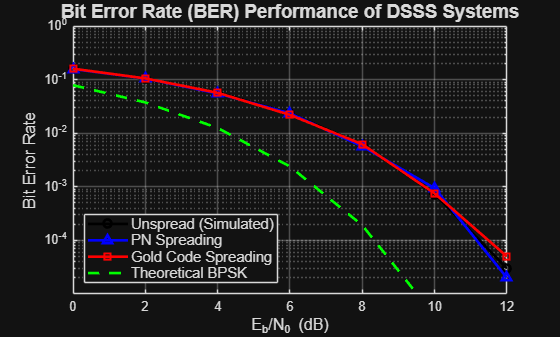


%% 5. Visualization and Performance Analysis
figure('Name', 'DSSS Performance Analysis', 'NumberTitle', 'off');
semilogy(EbNo_dB, ber_unspread, 'k-o', 'LineWidth', 2);
hold on; grid on;
semilogy(EbNo_dB, ber_pn, 'b-^', 'LineWidth', 2);
semilogy(EbNo_dB, ber_gold, 'r-s', 'LineWidth', 2);

% Theoretical BPSK Curve
ber_theoretical = qfunc(sqrt(2*10.^(EbNo_dB/10)));
semilogy(EbNo_dB, ber_theoretical, 'g--', 'LineWidth', 2);

title('Bit Error Rate (BER) Performance of DSSS Systems', 'FontSize', 14);
xlabel('E_b/N_0 (dB)', 'FontSize', 12);
ylabel('Bit Error Rate', 'FontSize', 12);
legend('Unspread (Simulated)', 'PN Spreading', 'Gold Code Spreading', ...
    'Theoretical BPSK', 'Location', 'southwest', 'FontSize', 11);
axis([min(EbNo_dB) max(EbNo_dB) 1e-5 1]);